# This live script explores and plots the effect of sudden jumps on input heading.

% This file uses conectivity with P-EG neurons.

clear; clf;

fixedThreshold = false;
jumpDistance = 120; % Heading change
currentStrenth = 0.0;
pulseLengthMulti = 3;
maxSpikeRate = 120; % An initial guess.
inputList=[33:48];  % Stimulus to E-PG neurons
SAVE_FIG = false;   % Store images in files

jumpDistance = 120; % Heading change
maxSpikeRate = 170; % An initial guess.

clearvars -except fixedThreshold jumpDistance currentStrenth pulseLengthMulti maxSpikeRate inputList SAVE_FIG;
% Drosophila corrected (2018) connectivity matrix including P-EG neurons
load('connectivity_matrix_drosophila_mine_case_5_9cols_labels1.mat');
disp('Drosophila corrected (2018) connectivity matrix including P-EG neurons')

Drosophila corrected (2018) connectivity matrix including P-EG neurons



%           [       35      :       52           ];
inputList = [n_P_EN+n_P_EG+1:n_P_EN+n_P_EG+n_E_PG]; % E-PG neurons indexes for Drosophila with 9 columns connected

% Find matrix elements with these label values
plus_1s_ind    = con_matrix == 1;plus_3s_ind    = con_matrix == 3;plus_1_1s_ind  = con_matrix == 1.1;
plus_0_9s_ind = con_matrix == 0.9;
plus_0_5s_ind  = con_matrix == 0.5;
plus_0_1s_ind = con_matrix == 0.1;
minus_1s_ind   = con_matrix == -1;minus_1_1s_ind = con_matrix == -1.1;minus_0_5s_ind  = con_matrix == -0.5;
minus_0_9s_ind = con_matrix == -0.9;
minus_0_1s_ind = con_matrix == -0.1;

% Fitness expected jump from column 2 to 6, starting with small values and bounds -100 to 100 and penalising 0 weights. Simulated Annealing.
% <entry version> <fitness> <bumpLocPre> <bumpLocPost> <bumpWidthPre> <final bump width> <E-PG peak spike rate> <5 or 8 x weight parameters>
parameter_set_drosophila = [5	0.0234854383940386	1.50000000000000	6	0.785398163397448	1.57079632679490	190	6.07203896674184	47.9173822984772	-35.6772759590409	-19.3358579258735	99.9680554605268] % Good

parameter_set_drosophila =     5.0000    0.0235    1.5000    6.0000    0.7854    1.5708  190.0000    6.0720   47.9174  -35.6773  -19.3359   99.9681



if size(parameter_set_drosophila, 2) == 5
    [plus_1s_value,plus_1_1s_value,minus_1s_value,minus_1_1s_value,plus_3s_value] = feval(@(x) x{:}, num2cell(parameter_set_drosophila));
elseif size(parameter_set_drosophila, 2) == 6
    [plus_1s_value,plus_1_1s_value,plus_0_5s_value,minus_1s_value,minus_1_1s_value,minus_0_5s_value] = feval(@(x) x{:}, num2cell(parameter_set_drosophila));
    plus_3s_value    = plus_1s_value * 3;
elseif size(parameter_set_drosophila, 2) == 7
    [plus_1s_value,plus_1_1s_value,plus_0_5s_value,minus_1s_value,minus_1_1s_value,minus_0_5s_value,plus_3s_value] = feval(@(x) x{:}, num2cell(parameter_set_drosophila));
elseif size(parameter_set_drosophila, 2) == 9
    [version,fitness,bump_width,peak_spike_rate_E_PG,plus_1s_value,plus_1_1s_value,minus_1s_value,minus_1_1s_value,plus_3s_value] = feval(@(x) x{:}, num2cell(parameter_set_drosophila));
    maxSpikeRate = peak_spike_rate_E_PG;
elseif size(parameter_set_drosophila, 2) == 12
    [version,fitness,bump_loc_pre,bump_loc_post,bump_width_pre,bump_width_post,peak_spike_rate_E_PG,plus_1s_value,plus_1_1s_value,minus_1s_value,minus_1_1s_value,plus_3s_value] = feval(@(x) x{:}, num2cell(parameter_set_drosophila));
    bump_width = bump_width_post;
    maxSpikeRate = peak_spike_rate_E_PG;
end

% If the connectivity matrix contains -0.9 values then is sinusoidal
% otherwise is the hardwired ratio
if any(any(minus_0_9s_ind))
    half_mult = 0.5;
else
    half_mult = 0.707;
end

minus_0_9s_value = minus_1_1s_value * 0.85355339;
minus_0_5s_value = minus_1_1s_value * half_mult;
minus_0_1s_value = minus_1_1s_value * 0.14644661;

plus_0_9s_value = plus_1_1s_value * 0.85355339;
plus_0_5s_value = plus_1_1s_value * half_mult;
plus_0_1s_value = plus_1_1s_value * 0.14644661;

% Print the parameter values
[plus_1s_value plus_1_1s_value plus_0_5s_value minus_1s_value minus_1_1s_value minus_0_5s_value plus_3s_value]

ans =     6.0720   47.9174   33.8776  -35.6773  -19.3359  -13.6705   99.9681


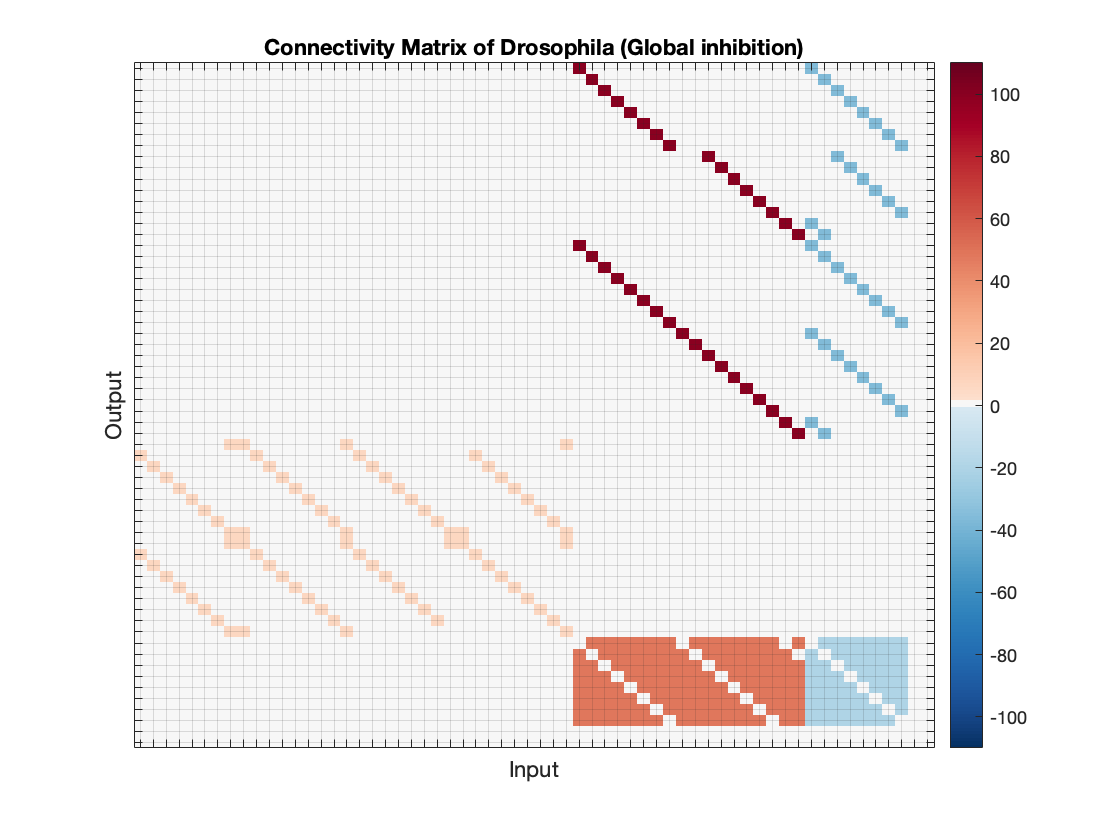

con_matrix(plus_1s_ind)    = plus_1s_value;con_matrix(plus_3s_ind)    = plus_3s_value;con_matrix(plus_1_1s_ind)  = plus_1_1s_value;con_matrix(plus_0_9s_ind)  = plus_0_9s_value;con_matrix(plus_0_5s_ind)  = plus_0_5s_value;con_matrix(plus_0_1s_ind)  = plus_0_1s_value;con_matrix(minus_1s_ind)   = minus_1s_value;con_matrix(minus_1_1s_ind) = minus_1_1s_value;con_matrix(minus_0_9s_ind) = minus_0_9s_value;con_matrix(minus_0_5s_ind) = minus_0_5s_value;con_matrix(minus_0_1s_ind) = minus_0_1s_value;

% Plot the connectivity matrix
plot_con_matrix(con_matrix, 'Connectivity Matrix of Drosophila (Global inhibition)', 'Input', 'Output', -110, 110, n_P_EN, n_P_EG, n_E_PG, n_Pintr);

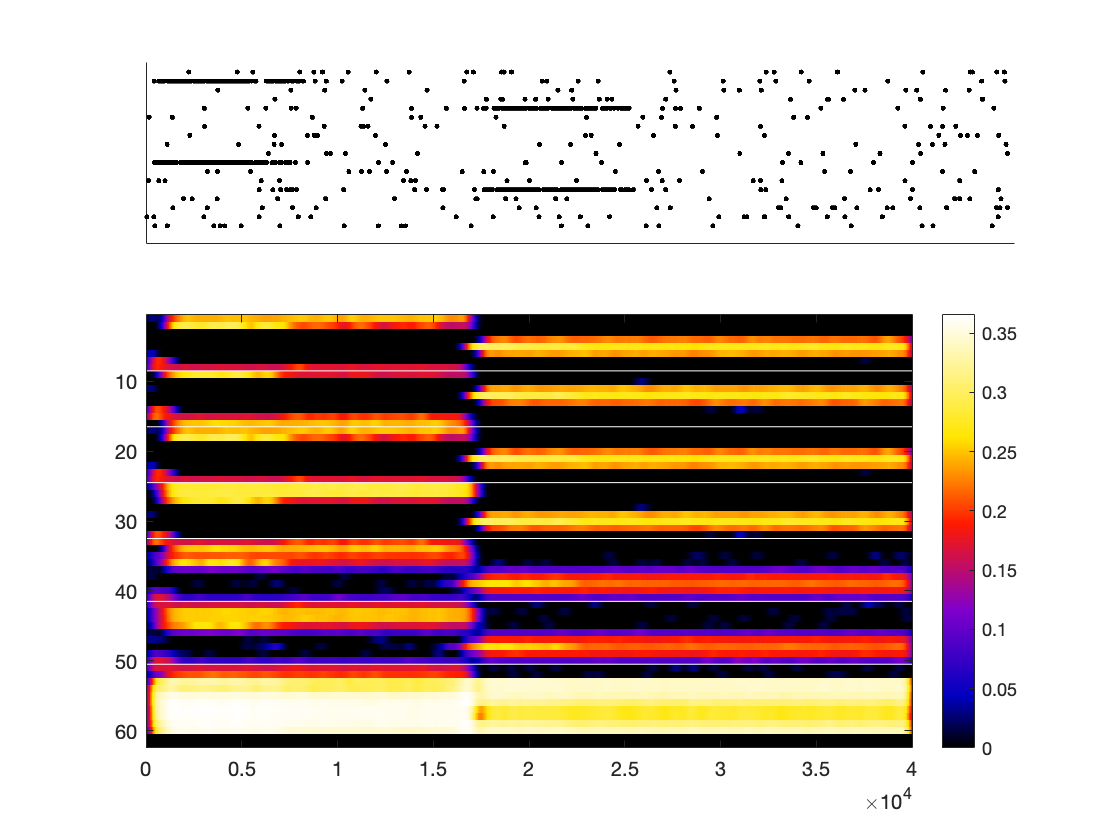

if SAVE_FIG
    title('');
    set(gca, 'FontSize', 16);
    set(findall(gcf, 'type', 'text'), 'FontSize', 16);
    path = './Reports/Report-6/';
    filename = strcat(path, 'connectivity-matrix-drosophila-global-inhib');
    fig = gcf;
    fig.PaperUnits = 'inches';
    fig.PaperPosition = [0 0 7 6]; % Outer Image size in inches
    print(filename, '-dpng', '-r300');        % Image resolution
    print(filename, '-dpdf', '-r300');        % Image resolution
end

figure();

% Run the network simulation and get bump width at the end
bump = runNetworkSimulation(con_matrix, 1, fixedThreshold, currentStrenth, jumpDistance, pulseLengthMulti, maxSpikeRate, inputList);

if SAVE_FIG
    set(gca, 'FontSize', 16);
    set(findall(gcf, 'type', 'text'), 'FontSize', 16);
    path = './Reports/Report-6/';
    filename = strcat(path, 'drosophila-full-jump120deg-extrCurrent0');
    fig = gcf;
    fig.PaperUnits = 'inches';
    fig.PaperPosition = [0 0 7 5.25]; % Outer Image size in inches
end

bumpWidth = bump.bumpWidth;
% Print the bump width
bumpWidth * 180 / pi

ans = 90


bump.bumpLocPre

ans = 1.5000

bump.bumpLocPost

ans = 5


bump.bumpWidthPre  * 180 / pi

ans = 45

bump.bumpWidthPost * 180 / pi

ans = 90


bump.spikeRate % Display the spike rates of the neurons

ans =      0
     0
     0
   140
   190
   160
     0
     0
     0
     0


jumpDistance = 120; % Heading change
maxSpikeRate = 170; % An initial guess.

clearvars -except fixedThreshold jumpDistance currentStrenth pulseLengthMulti maxSpikeRate inputList SAVE_FIG;
% Drosophila corrected (2018) connectivity matrix with localised inhibition including P-EG neurons
load('connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1.mat');
disp('Drosophila corrected (2018) connectivity matrix with localised inhibition including P-EG neurons')

Drosophila corrected (2018) connectivity matrix with localised inhibition including P-EG neurons



%           [       35      :       52           ];
inputList = [n_P_EN+n_P_EG+1:n_P_EN+n_P_EG+n_E_PG]; % E-PG neurons indexes for Drosophila with 9 columns connected

% Find matrix elements with these label values
plus_1s_ind    = con_matrix == 1;plus_3s_ind    = con_matrix == 3;plus_1_1s_ind  = con_matrix == 1.1;
plus_0_9s_ind = con_matrix == 0.9;
plus_0_5s_ind  = con_matrix == 0.5;
plus_0_1s_ind = con_matrix == 0.1;
minus_1s_ind   = con_matrix == -1;minus_1_1s_ind = con_matrix == -1.1;minus_0_5s_ind  = con_matrix == -0.5;
minus_0_9s_ind = con_matrix == -0.9;
minus_0_1s_ind = con_matrix == -0.1;

  % Fitness expected jump from column 2 to 6, optimising all weights with bounds -100 to 100 and penalising 0 weights. Particle Swarm.
  % <entry version> <fitness> <bumpLocPre> <bumpLocPost> <bumpWidthPre> <final bump width> <E-PG peak spike rate> <5 or 8 x weight parameters>
  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-26-additive-weightedobj-particleswarm_eddie.mat
%  parameter_set_drosophila = [5	0.0234849547773483	1.50000000000000	6	0.785398163397448	1.57079632679490	220	22.6051396076308	92.6937229479011	-68.2694968182500	-22.2050248827029	100] % Good
%  parameter_set_drosophila = [5	1.06292499854510e-07	2	6	1.57079632679490	1.57079632679490	220	20.5121145114831	100	-64.0031579690439	-27.9103908985403	98.3064621237903] % Good
%  parameter_set_drosophila = [5	0.0234849547773498	1.50000000000000	6	0.785398163397448	1.57079632679490	230	15.8768272473890	87.1620497035514	-59.9441885786663	-19.1664578843208	100] % Good
%  parameter_set_drosophila = [5	0.0234849547773483	1.50000000000000	6	0.785398163397448	1.57079632679490	220	26.8474113345740	84.8656399736654	-41.3826301581959	-21.3328088562438	62.7511607031937] % Good
%  parameter_set_drosophila = [5	0.0234849547773483	1.50000000000000	6	0.785398163397448	1.57079632679490	220	26.2014714312860	95.1486136800559	-29.1852181547803	-31.2878214393677	46.2310395569378] % Good
%  parameter_set_drosophila = [5	0.0234849547773524	1.50000000000000	6	0.785398163397448	1.57079632679490	230	15.3732019052905	66.3011669078145	-53.8635235035179	-19.0916314503329	91.6271520344747] % Good
%  parameter_set_drosophila = [5	0.143939500231894	1.50000000000000	1.50000000000000	0.785398163397448	0.785398163397448	220	25.5619297969840	91.3837941914360	-45.6851827922786	-30.4661731604180	67.7269526217434] % Good
%  parameter_set_drosophila = [5	0.143939500231894	1.50000000000000	1.50000000000000	0.785398163397448	0.785398163397448	240	33.4675110522466	77.0336520103477	-35.4329978509190	-22.3192314659146	51.0591231515483] % Good
%  parameter_set_drosophila = [5	0.0234849547773509	1.50000000000000	6	0.785398163397448	1.57079632679490	230	29.4643045795309	91.7613590997187	-22.2877413892210	-15.5921505142477	37.2445003912647] % Good
%  parameter_set_drosophila = [5	0.143939500231894	1.50000000000000	1.50000000000000	0.785398163397448	0.785398163397448	240	31.7961250684478	85.7845154539781	-52.6578981191827	-27.6120664643556	72.9724696692317] % Good

  % Fitness expected jump from column 2 to 6, re-optimising only the inhibitory weights with bounds -100 to 100 and penalising 0 weights. Particle Swarm.
  % <entry version> <fitness> <bumpLocPre> <bumpLocPost> <bumpWidthPre> <final bump width> <E-PG peak spike rate> <5 or 8 x weight parameters>
  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-25-additive-weightedobj-particleswarm_eddie.mat
%  parameter_set_drosophila = [5	1.19507745673836e-07	2	6	1.57079632679490	1.57079632679490	210	7.87200000000000	47.9485034890243	-45.7834414678533	-15.0475843703388	99.6254339184113] % Good
%  parameter_set_drosophila = [5	1.19508087058765e-07	2	6	1.57079632679490	1.57079632679490	220	7.87200000000000	47.2524155235818	-47.2133042876606	-13.1427332888745	98.9217097510870] % Good
%  parameter_set_drosophila = [5	0.0234849679925871	1.50000000000000	6	0.785398163397448	1.57079632679490	200	7.87200000000000	47.8852892944175	-48.6786101368865	-16.2752977217382	99.0544426067553] % Good
%  parameter_set_drosophila = [5	0.120454664962283	2	1.50000000000000	1.57079632679490	0.785398163397448	230	7.87200000000000	46.3200908976792	-49.0497715561119	-17.3816521301359	99.8694956790805] % Good
%  parameter_set_drosophila = [5	0.0234849681703395	1.50000000000000	6	0.785398163397448	1.57079632679490	210	7.86531968165797	46.6968239947936	-47.0296039459295	-15.3367936960038	98.0042000000000] % Good
%  parameter_set_drosophila = [5	0.143939513447132	2	1	1.57079632679490	0	230	7.87200000000000	46.5462074217127	-48.2137583050083	-17.0283909674898	98.2079510249247] % Good
%  parameter_set_drosophila = [5	1.19507741119506e-07	2	6	1.57079632679490	1.57079632679490	230	7.87200000000000	47.7179198429039	-47.3167503632711	-15.4919469772304	98.6371868823137] % Good
%  parameter_set_drosophila = [5	0.0234849694870889	1.50000000000000	6	0.785398163397448	1.57079632679490	200	7.81853900179082	47.4455369326122	-46.9606920618911	-12.0355092015695	99.4301808816503] % Good
%  parameter_set_drosophila = [5	0.0719697104223350	3	4.50000000000000	1.57079632679490	2.35619449019235	210	7.87200000000000	46.2165000000000	-43.2903199884894	-9.88168979728104	98.3442642020183] % Good
%  parameter_set_drosophila = [5	0.0477273922350133	1.50000000000000	7	0.785398163397448	1.57079632679490	230	7.87200000000000	46.5847727987277	-49.8504030546202	-15.5821806359570	99.1885136821686] % Good
%  parameter_set_drosophila = [5	0.0242425437750331	3	6	1.57079632679490	1.57079632679490	200	7.87200000000000	46.3728563858849	-45.6714225559537	-11.0097136493043	98.8473392503980] % Good
%  parameter_set_drosophila = [5	1.24989961691990e-07	2	6	1.57079632679490	1.57079632679490	210	7.69854483955316	46.2165000000000	-48.1718449775806	-12.2703311714954	99.0172517238769] % Good
%  parameter_set_drosophila = [5	0.0234849679925881	1.50000000000000	6	0.785398163397448	1.57079632679490	210	7.87200000000000	47.3974559773239	-47.3262189217951	-15.8238782564451	99.4033663868673] % Good
%  parameter_set_drosophila = [5	0.0242425437501845	3	6	1.57079632679490	1.57079632679490	220	7.87200000000000	46.6205089612408	-47.3563142056391	-14.5171985290589	98.4044942558072] % Good
%  parameter_set_drosophila = [5	0.0234849797200962	1.50000000000000	6	0.785398163397448	1.57079632679490	200	7.55539430246461	47.9623355174027	-46.0305174666706	-10.6619090987302	99.1747429474588] % Good 
%  parameter_set_drosophila = [5	0.167424361931980	1.50000000000000	1	0.785398163397448	0	230	7.87200000000000	47.2734547727592	-47.4274317235856	-17.1799576122327	98.1453523916041] % Good
%  parameter_set_drosophila = [5	0.167424361931988	1.50000000000000	1	0.785398163397448	0	200	7.87200000000000	46.5098770385415	-46.1686622985130	-15.0453826211349	99.7914317959017] % Good
%  parameter_set_drosophila = [5	1.19507738071258e-07	2	6	1.57079632679490	1.57079632679490	230	7.87200000000000	48.1821215516376	-48.1011569143674	-17.0825818684999	99.5626578848794] % Good
%  parameter_set_drosophila = [5	0.0234849679928044	1.50000000000000	6	0.785398163397448	1.57079632679490	210	7.87200000000000	46.4866309888227	-50.5242879815246	-13.3782845215809	99.7603488614167] % Good

  % Fitness expected jump from column 2 to 6, re-optimising all weights with bounds -100 to 100 and penalising 0 weights. Particle Swarm.
  % <entry version> <fitness> <bumpLocPre> <bumpLocPost> <bumpWidthPre> <final bump width> <E-PG peak spike rate> <5 or 8 x weight parameters>
  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma20-29-additive-weightedobj-particleswarm_eddie.mat
%    inhibition_distr_type = 'gaussian';
%    inhibition_width_sigma = 20.0;
%   parameter_set_drosophila = [5	7.79503903869090e-08	2	6	1.57079632679490	1.57079632679490	200	11.9920367512486	100	-39.9865283711984	-61.8527956012391	79.4307820650153] % instanteneous
%   parameter_set_drosophila = [5	0.0261111890589443	1.50000000000000	6	0.785398163397448	1.57079632679490	260	97.5014879475085	98.2616751412975	-88.1338987171477	-91.0960001615220	92.2511668959056] % instanteneous


  % Fitness expected jump from column 2 to 6, re-optimising all weights with bounds -100 to 100 and penalising 0 weights. Particle Swarm.
  % <entry version> <fitness> <bumpLocPre> <bumpLocPost> <bumpWidthPre> <final bump width> <E-PG peak spike rate> <5 or 8 x weight parameters>
  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma10-29-additive-weightedobj-particleswarm_eddie.mat
%    inhibition_distr_type = 'gaussian';
%    inhibition_width_sigma = 10.0;
%   parameter_set_drosophila = [5	0.239444522392278	7.50000000000000	7	0.785398163397448	1.57079632679490	220	20.5026065058936	69.9917787047252	-55.8593907352733	-24.9466872745677	92.0996779131558] % instanteneous

  % Fitness expected jump from column 2 to 6, re-optimising all weights with bounds -100 to 100 and penalising 0 weights. Particle Swarm.
  % <entry version> <fitness> <bumpLocPre> <bumpLocPost> <bumpWidthPre> <final bump width> <E-PG peak spike rate> <5 or 8 x weight parameters>
  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma5-29-additive-weightedobj-particleswarm_eddie.mat
%    inhibition_distr_type = 'gaussian';
%    inhibition_width_sigma = 5.0;
%   parameter_set_drosophila = [5	0.142222300170057	6	6	1.57079632679490	1.57079632679490	210	15.8994674305211	37.2877002095241	-39.7439764711448	-27.5452476168577	65.0930621946662] % instanteneous

% Fitness expected jump from column 2 to 6, re-optimising all weights with bounds -100 to 100 and penalising 0 weights. Particle Swarm.
  % <entry version> <fitness> <bumpLocPre> <bumpLocPost> <bumpWidthPre> <final bump width> <E-PG peak spike rate> <5 or 8 x weight parameters>
  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma2-29-additive-weightedobj-particleswarm_eddie.mat
%    inhibition_distr_type = 'gaussian';
%    inhibition_width_sigma = 2.0;
%   parameter_set_drosophila = [5	0.0355556345295182	3	6	1.57079632679490	1.57079632679490	180	8.99471090471328	61.1382872035463	-39.9866469215198	-26.0016247141137	87.7742653786371] % instanteneous


  % Fitness expected jump from column 2 to 6, re-optimising all weights with bounds -100 to 100 and penalising 0 weights. Particle Swarm.
  % <entry version> <fitness> <bumpLocPre> <bumpLocPost> <bumpWidthPre> <final bump width> <E-PG peak spike rate> <5 or 8 x weight parameters>
  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma1-25-additive-weightedobj-particleswarm_eddie.mat
%  inhibition_distr_type = 'gaussian';
%  inhibition_width_sigma = 1.0;
%  parameter_set_drosophila = [5	0.0234849679925864	1.50000000000000	6	0.785398163397448	1.57079632679490	220	7.87200000000000	47.5158016795147	-45.8342060945311	-22.4366194460692	98.1308533588746] % instanteneous drifts a bit
%  parameter_set_drosophila = [5	0.0242425437501622	3	6	1.57079632679490	1.57079632679490	200	7.87200000000000	47.5407786684970	-47.3918502653450	-23.4942612207858	99.8467860590339] % instanteneous
%  parameter_set_drosophila = [5	0.0484849679925864	3	5	1.57079632679490	1.57079632679490	220	7.87200000000000	46.6777175970246	-47.5796711933252	-23.2897036829336	98.8920979131384] % instanteneous
%  parameter_set_drosophila = [5	0.0234849679925864	1.50000000000000	6	0.785398163397448	1.57079632679490	230	7.87200000000000	47.6748679065047	-48.2555316451553	-25.4359718114558	99.3803171926161] % instanteneous

  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma0.9-25-additive-weightedobj-particleswarm_eddie.mat
%  inhibition_distr_type = 'gaussian';
%  inhibition_width_sigma = 0.9;
%  parameter_set_drosophila = [5	1.19507737939432e-07	2	6	1.57079632679490	1.57079632679490	210	7.87200000000000	46.2165000000000	-46.0753044820010	-20.1925480945560	98.6638945240470] % instanteneous
%  parameter_set_drosophila = [5	0.167424361931980	1.50000000000000	1	0.785398163397448	0	230	7.87200000000000	47.2293992853239	-48.1350909257739	-24.4598179948934	98.6358318703094] % instanteneous
%  parameter_set_drosophila = [5	0.0234849679925864	1.50000000000000	6	0.785398163397448	1.57079632679490	230	7.87200000000000	47.9830707849427	-48.2382880957950	-23.5254088149971	98.3649301100318] % instanteneous

  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma0.8-25-additive-weightedobj-particleswarm_eddie.mat
%  inhibition_distr_type = 'gaussian';
%  inhibition_width_sigma = 0.8;
%  parameter_set_drosophila = [5	1.43978742179605e-07	2	6	1.57079632679490	1.57079632679490	220	7.34803773068470	46.2521506658480	-45.1646542972724	-19.8500583916050	98.2776264975180] % instanteneous
%  parameter_set_drosophila = [5	0.0234849679925864	1.50000000000000	6	0.785398163397448	1.57079632679490	200	7.87200000000000	46.2894704213451	-48.7637308480016	-20.3241412047531	99.9777216566899] % instanteneous
%  parameter_set_drosophila = [5	0.0234849779463726	1.50000000000000	6	0.785398163397448	1.57079632679490	210	7.59127720681778	46.6408225027649	-45.6689483976751	-15.7815741437834	98.4542460061673] % instanteneous
%  parameter_set_drosophila = [5	0.0234849679925864	1.50000000000000	6	0.785398163397448	1.57079632679490	230	7.87200000000000	47.0651934443502	-47.4238813185708	-21.5034717488803	99.3500795415795] % instanteneous
%  parameter_set_drosophila = [5	1.19507738027458e-07	2	6	1.57079632679490	1.57079632679490	210	7.87200000000000	46.2746940449638	-45.5517971538924	-17.2840138152833	98.1616531445963] % instanteneous

  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma0.7-25-additive-weightedobj-particleswarm_eddie.mat
%  inhibition_distr_type = 'gaussian';
%  inhibition_width_sigma = 0.7;
%  parameter_set_drosophila = [5	1.19507737963105e-07	2	6	1.57079632679490	1.57079632679490	200	7.87200000000000	46.2404281184040	-48.2896712917134	-17.9366353440088	98.1399253765226] % instanteneous
%  parameter_set_drosophila = [5	1.19507738040694e-07	2	6	1.57079632679490	1.57079632679490	220	7.87200000000000	47.6783915393434	-46.7504048829477	-17.2141654516639	98.7492292292391] % instanteneous
%  parameter_set_drosophila = [5	1.19507753610652e-07	2	6	1.57079632679490	1.57079632679490	200	7.87200000000000	48.2153056368811	-46.2138376304500	-14.6945192211375	98.4029474577367] % instanteneous
%  parameter_set_drosophila = [5	1.19507737983246e-07	2	6	1.57079632679490	1.57079632679490	210	7.87200000000000	47.0138822487579	-46.6197336234880	-17.6313494342780	98.2452788371835] % almost instanteneous
  
  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma0.6-25-additive-weightedobj-particleswarm_eddie.mat
%  inhibition_distr_type = 'gaussian';
%  inhibition_width_sigma = 0.6;
%  parameter_set_drosophila = [5	0.0477273922350112	1.50000000000000	7	0.785398163397448	1.57079632679490	240	7.87200000000000	46.7293342456163	-49.2961916650969	-16.3984247145891	98.1717057704041] % almost instanteneous
%  parameter_set_drosophila = [5	0.167424361931981	1.50000000000000	1	0.785398163397448	0	240	7.87200000000000	47.4608005904460	-48.4998410399878	-17.0591848930638	99.0652755942597] % so-so instanteneous

  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma0.5-25-additive-weightedobj-particleswarm_eddie.mat
%  inhibition_distr_type = 'gaussian';
%  inhibition_width_sigma = 0.5;
%  parameter_set_drosophila = [5	1.19525387298284e-07	2	6	1.57079632679490	1.57079632679490	220	7.87200000000000	48.1428675702974	-53.9162774552087	-11.1812131855969	99.4382698813610] % almost instateneous
%  parameter_set_drosophila = [5	0.0234849685106355	1.50000000000000	6	0.785398163397448	1.57079632679490	210	7.86118616180427	47.8020036993688	-50.6871464359946	-9.89943780050181	98.5985424157065] % instateneous
%  parameter_set_drosophila = [5	0.0477273923575791	1.50000000000000	7	0.785398163397448	1.57079632679490	210	7.87176416312881	48.1302506457679	-46.9510062843740	-10.2383315135064	98.7297030840417] % instateneous

  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma0.45-25-additive-weightedobj-particleswarm_eddie.mat
%  inhibition_distr_type = 'gaussian';
%  inhibition_width_sigma = 0.45;
%  parameter_set_drosophila = [5	0.0712122408068697	1.50000000000000	7.50000000000000	0.785398163397448	0.785398163397448	210	7.87200000000000	47.0643977173936	-53.5315932108145	-10.3835482593165	99.1858018554580] % instateneous
%  parameter_set_drosophila = [5	0.0469698193100487	1.50000000000000	6.50000000000000	0.785398163397448	0.785398163397448	210	7.87200000000000	47.3564569313443	-59.1953350914242	-8.64208533886259	98.0188358033921] % almost instanteneous

  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma0.4-25-additive-weightedobj-particleswarm_eddie.mat
%  inhibition_distr_type = 'gaussian';
%  inhibition_width_sigma = 0.4;
%  parameter_set_drosophila = [5	0.0477273933933868	1.50000000000000	7	0.785398163397448	1.57079632679490	230	7.87200000000000	46.4385488157865	-53.6715878469669	-9.08917570780942	100.004200000000] % gradual (at 90deg gradual 8 out of 10)

parameter_set_drosophila =     5.0000    0.0477    1.5000    7.0000    0.7854    1.5708  230.0000    7.8720   46.4385  -53.6716   -9.0892  100.0042



  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma0.35-25-additive-weightedobj-particleswarm_eddie.mat
  inhibition_distr_type = 'gaussian';
  inhibition_width_sigma = 0.35;
  parameter_set_drosophila = [5	0.0794873705533528	1.50000000000000	7.50000000000000	0.785398163397448	0.785398163397448	230	7.87200000000000	47.6694620232075	-69.4868736534706	-11.7884218044897	98.5027106906458] % gradual

parameter_set_drosophila =     5.0000    0.0795    1.5000    7.5000    0.7854    0.7854  230.0000    7.8720   47.6695  -69.4869  -11.7884   98.5027


%  parameter_set_drosophila = [5	0.0477273925097464	2	7.50000000000000	1.57079632679490	0.785398163397448	230	7.86617533824912	46.7072471288219	-72.1897477061516	-10.2232881083744	100.004200000000] % gradual

  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma0.3-25-additive-weightedobj-particleswarm_eddie.mat
%  inhibition_distr_type = 'gaussian';
%  inhibition_width_sigma = 0.3;
%  parameter_set_drosophila = [5	0.0410258553744100	3	5	1.57079632679490	1.57079632679490	230	7.32629210897286	46.5822903382586	-68.9893563035456	-9.00351481598619	99.5796430256586] % gradual
%  parameter_set_drosophila = [5	0.167424363619215	1.50000000000000	1	0.785398163397448	0	240	7.81266821714472	46.3590537449761	-77.5105722559297	-11.0657653891827	99.9324115844283] % gradual

  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma0.2-25-additive-weightedobj-particleswarm_eddie.mat
%  inhibition_distr_type = 'gaussian';
%  inhibition_width_sigma = 0.2;
%  parameter_set_drosophila = [5	0.0500005361985701	2	7.50000000000000	1.57079632679490	0.785398163397448	220	6.49294268585981	47.6455336648417	-72.9716112751814	-6.48274668190138	99.6934392409853] % gradual (at 90deg change 9-10 out of 10 gradual)
%  parameter_set_drosophila = [5	0.170513011574560	1.50000000000000	1	0.785398163397448	0	230	7.87200000000000	47.6504352758740	-99.4769561440563	-25.9595208768603	98.2717909717878] % gradual
%  parameter_set_drosophila = [5	0.0500003869416324	2	7.50000000000000	1.57079632679490	0.785398163397448	230	7.05475122033382	47.1830669629999	-73.2728692926463	-6.57473275154917	98.7991584798917] % gradual
%  parameter_set_drosophila = [5	0.0712122496964177	1.50000000000000	7.50000000000000	0.785398163397448	0.785398163397448	230	7.87200000000000	46.5562395498067	-82.7271548646743	-8.06537699637874	98.2134862623078] % gradual

  % optimise_connectivity_weights_results_for_connectivity_matrix_drosophila_mine_case_5_9cols_localised_3_labels1-sigma0.1-25-additive-weightedobj-particleswarm_eddie.mat
%  inhibition_distr_type = 'gaussian';
%  inhibition_width_sigma = 0.1;
%  parameter_set_drosophila = [5	0.170513155233403	1.50000000000000	1	0.785398163397448	0	230	6.55795895179780	46.2813837588992	-100	-20.0071110292163	98.8757579757439] % gradual
%  parameter_set_drosophila = [5	0.0410274553910059	3	5	1.57079632679490	1.57079632679490	230	6.63062938291224	46.2165000000000	-94.0887004124376	-5.42235124881989	98.0128520027667] % gradual
%  parameter_set_drosophila = [5	0.170513011574560	1.50000000000000	1	0.785398163397448	0	230	7.87200000000000	48.2165000000000	-90.7674007927552	-17.5082766852232	99.3271753952298] % gradual unreliable
%  parameter_set_drosophila = [5	0.0794874215602080	1.50000000000000	7.50000000000000	0.785398163397448	0.785398163397448	230	7.74167395486623	47.8798494588973	-91.4574272207449	-7.14688629202682	99.9051170413800] % gradual
  
if size(parameter_set_drosophila, 2) == 5
    [plus_1s_value,plus_1_1s_value,minus_1s_value,minus_1_1s_value,plus_3s_value] = feval(@(x) x{:}, num2cell(parameter_set_drosophila));
elseif size(parameter_set_drosophila, 2) == 6
    [plus_1s_value,plus_1_1s_value,plus_0_5s_value,minus_1s_value,minus_1_1s_value,minus_0_5s_value] = feval(@(x) x{:}, num2cell(parameter_set_drosophila));
    plus_3s_value    = plus_1s_value * 3;
elseif size(parameter_set_drosophila, 2) == 7
    [plus_1s_value,plus_1_1s_value,plus_0_5s_value,minus_1s_value,minus_1_1s_value,minus_0_5s_value,plus_3s_value] = feval(@(x) x{:}, num2cell(parameter_set_drosophila));
elseif size(parameter_set_drosophila, 2) == 9
    [version,fitness,bump_width,peak_spike_rate_E_PG,plus_1s_value,plus_1_1s_value,minus_1s_value,minus_1_1s_value,plus_3s_value] = feval(@(x) x{:}, num2cell(parameter_set_drosophila));
    maxSpikeRate = peak_spike_rate_E_PG;
elseif size(parameter_set_drosophila, 2) == 12
    [version,fitness,bump_loc_pre,bump_loc_post,bump_width_pre,bump_width_post,peak_spike_rate_E_PG,plus_1s_value,plus_1_1s_value,minus_1s_value,minus_1_1s_value,plus_3s_value] = feval(@(x) x{:}, num2cell(parameter_set_drosophila));
    bump_width = bump_width_post;
    maxSpikeRate = peak_spike_rate_E_PG;
end


num_of_samples = n_E_PG / 2;
if num_of_samples == 8
    num_of_samples = 9; % That is because with 8 samples it does not approximate Tom's values
end
inhibition_dist = get_inhib_distr_vector(inhibition_distr_type, num_of_samples, inhibition_width_sigma);
inhibition_dist

inhibition_dist =     0.0000    0.0035    0.0806    0.5329    1.0000    0.5329    0.0806    0.0035    0.0000


% If the connectivity matrix contains -0.9 values then is sinusoidal
% otherwise is the hardwired ratio
if any(any(minus_0_9s_ind))
    half_mult = inhibition_dist(3); % 0.5;
else
    half_mult = 0.707;
end

minus_0_9s_value = minus_1_1s_value *  inhibition_dist(4);
minus_0_5s_value = minus_1_1s_value * half_mult;
minus_0_1s_value = minus_1_1s_value * inhibition_dist(2);

plus_0_9s_value = plus_1_1s_value * inhibition_dist(4);
plus_0_5s_value = plus_1_1s_value * half_mult;
plus_0_1s_value = plus_1_1s_value * inhibition_dist(2);

% Print the parameter values
[plus_1s_value plus_1_1s_value plus_0_5s_value minus_1s_value minus_1_1s_value minus_0_5s_value plus_3s_value]

ans =     7.8720   47.6695    3.8441  -69.4869  -11.7884   -0.9506   98.5027


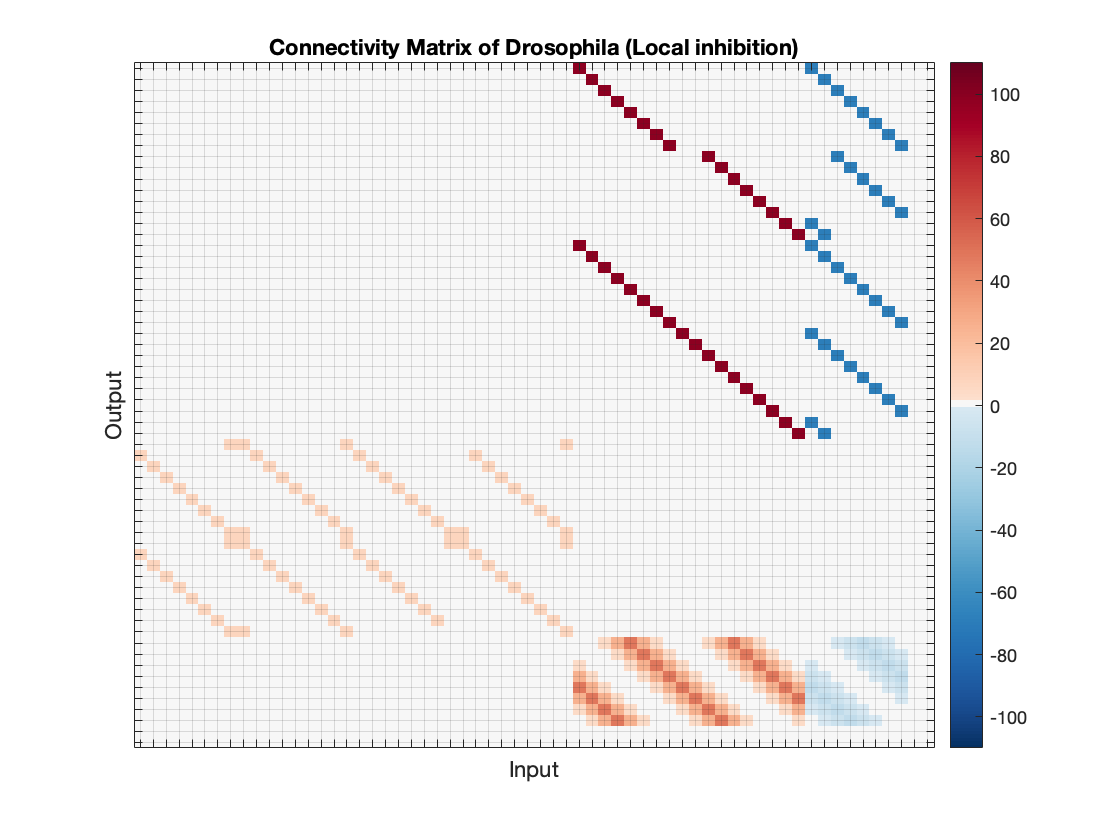

con_matrix(plus_1s_ind)    = plus_1s_value;con_matrix(plus_3s_ind)    = plus_3s_value;con_matrix(plus_1_1s_ind)  = plus_1_1s_value;con_matrix(plus_0_9s_ind)  = plus_0_9s_value;con_matrix(plus_0_5s_ind)  = plus_0_5s_value;con_matrix(plus_0_1s_ind)  = plus_0_1s_value;con_matrix(minus_1s_ind)   = minus_1s_value;con_matrix(minus_1_1s_ind) = minus_1_1s_value;con_matrix(minus_0_9s_ind) = minus_0_9s_value;con_matrix(minus_0_5s_ind) = minus_0_5s_value;con_matrix(minus_0_1s_ind) = minus_0_1s_value;

% Plot the connectivity matrix
plot_con_matrix(con_matrix, 'Connectivity Matrix of Drosophila (Local inhibition)', 'Input', 'Output', -110, 110, n_P_EN, n_P_EG, n_E_PG, n_Pintr);

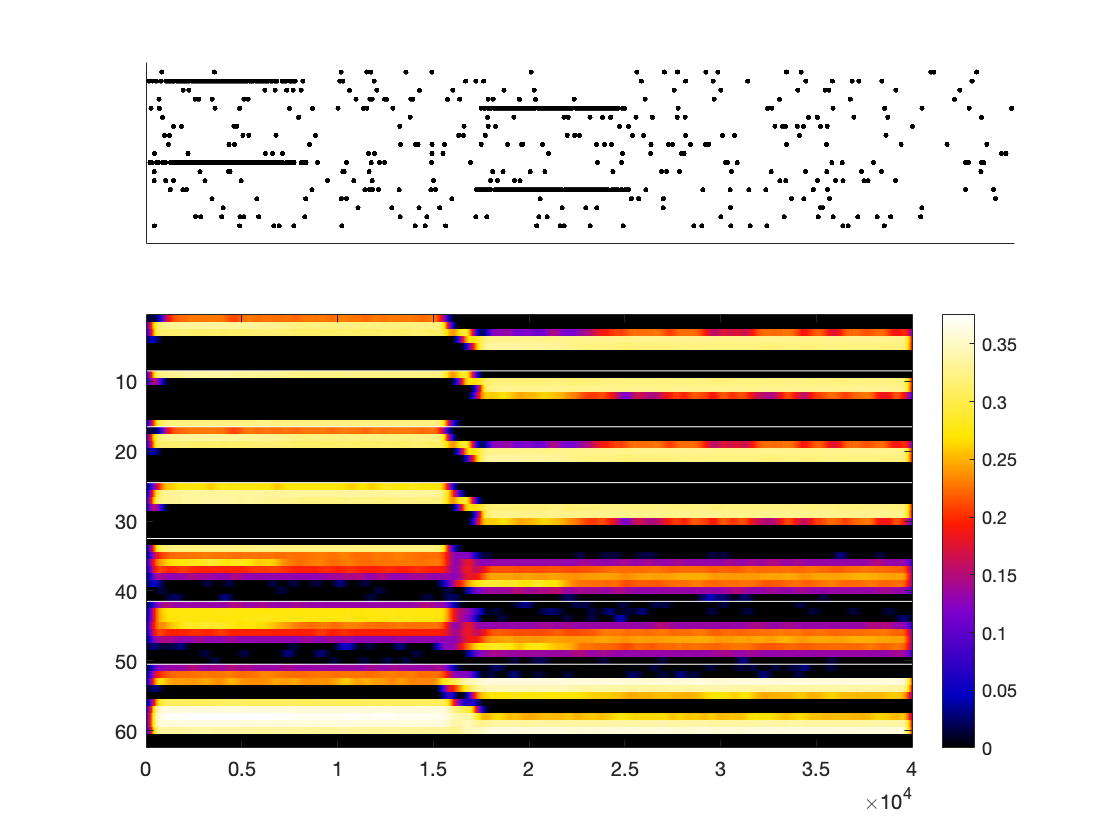

figure();

% Run the network simulation and get bump width at the end
bump = runNetworkSimulation(con_matrix, 1, fixedThreshold, currentStrenth, jumpDistance, pulseLengthMulti, maxSpikeRate, inputList);

bumpWidth = bump.bumpWidth;
% Print the bump width
bumpWidth * 180 / pi

ans = 90


bump.bumpLocPre

ans = 2

bump.bumpLocPost

ans = 4


bump.bumpWidthPre  * 180 / pi

ans = 90

bump.bumpWidthPost * 180 / pi

ans = 90


bump.spikeRate % Display the spike rates of the neurons

ans =      0
     0
   150
   230
   230
     0
     0
     0
     0
   230


clearvars -except fixedThreshold jumpDistance currentStrenth pulseLengthMulti maxSpikeRate inputList SAVE_FIG;
% Locust connectivity matrix with TB1 weights following sinusoidal distribution and separate weights
load('connectivity_matrix_locust_mine_case_6_with3s_labels_1.mat');
disp('Locust connectivity matrix with corrected TB1-to-TB1 weights following sinusoidal distribution and separate weights')

Locust connectivity matrix with corrected TB1-to-TB1 weights following sinusoidal distribution and separate weights



jumpDistance = 180; % Heading change
maxSpikeRate = 190; % Initial guess

%           [       33      :       48           ];
inputList = [n_P_EN+n_P_EG+1:n_P_EN+n_P_EG+n_E_PG]; % E-PG neurons indexes for locust

% Find matrix elements with these label values
plus_1s_ind    = con_matrix == 1;plus_3s_ind    = con_matrix == 3;plus_1_1s_ind  = con_matrix == 1.1;
plus_0_9s_ind = con_matrix == 0.9;
plus_0_5s_ind  = con_matrix == 0.5;
plus_0_1s_ind = con_matrix == 0.1;
minus_1s_ind   = con_matrix == -1;minus_1_1s_ind = con_matrix == -1.1;minus_0_5s_ind  = con_matrix == -0.5;
minus_0_9s_ind = con_matrix == -0.9;
minus_0_1s_ind = con_matrix == -0.1;

  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma0.1-29-additive-weightedobj-particleswarm_eddie.mat
%   inhibition_distr_type = 'gaussian';
%   inhibition_width_sigma = 0.1;
%   parameter_set_locust = [  5	0.0261111890605246	1.50000000000000	6	0.785398163397448	1.57079632679490	190	13.2952886194822	68.9335016997919	-12.2962726388568	-28.1884672549386	18.4103297965085] % gradual (selected)
%   parameter_set_locust = [  5	0.106666744644949	3	4	1.57079632679490	1.57079632679490	230	10.7534515124594	95.6610905171889	-67.9346728427044	-40.0469522226235	77.9452678491708] % gradual

  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma0.2-29-additive-weightedobj-particleswarm_eddie.mat
%   inhibition_distr_type = 'gaussian';
%   inhibition_width_sigma = 0.2;
%   parameter_set_locust = [  5	0.106666744614526	4	5	1.57079632679490	1.57079632679490	210	14.2818905767986	92.1925095270727	-77.2349439693607	-66.9804865130474	30.4390075566020] % gradual (a bit unreliable) (selected)
%   parameter_set_locust = [  5	0.0355556335035885	3	6	1.57079632679490	1.57079632679490	180	14.9905438008629	100	-29.4396908725168	-15.2839181099234	13.2923347237831] % gradual weak
%   parameter_set_locust = [  5	0.0261111891110956	2	6.50000000000000	1.57079632679490	0.785398163397448	190	16.3356277576986	83.9211199750694	-61.9936129595180	-10.4884112274095	12.9011176932872] % gradual weak shaky
%   parameter_set_locust = [  5	0.0711111893345082	2	4	1.57079632679490	1.57079632679490	210	14.0230290290674	99.5822366197205	-67.4357771275366	-9.65215566257545	47.3884439085455] % gradual shaky

  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma0.3-29-additive-weightedobj-particleswarm_eddie.mat
%   inhibition_distr_type = 'gaussian';
%   inhibition_width_sigma = 0.3;
%   parameter_set_locust = [  5	7.79482451488671e-08	2	6	1.57079632679490	1.57079632679490	220	13.0013552003923	100	-42.5175956766494	-13.7753777608579	52.7180896974101] % gradual
%   parameter_set_locust = [  5	0.0355556341169054	2	5	1.57079632679490	1.57079632679490	220	9.41835604417698	89.7533145022373	-43.3765140047743	-9.88269528104679	63.4950208679144] % gradual
%   parameter_set_locust = [  5	0.0972223001700569	3	4.50000000000000	1.57079632679490	0.785398163397448	220	15.7322252516399	77.9337488986632	-68.5465609206310	-17.6079032193445	53.9907331839456] % gradual
%   parameter_set_locust = [  5	0.0522223001720927	1	6	0	1.57079632679490	200	15.3579788257347	64.1850750770227	-34.8970466588240	-12.1064374199709	21.6054670762111] % gradual shaky
%   parameter_set_locust = [  5	0.0616667446145095	2	4.50000000000000	1.57079632679490	0.785398163397448	210	14.7821496592841	100	-46.9464403497651	-19.6676353263388	36.2424669586288] % gradual shaky
%   parameter_set_locust = [  5	0.0616667446215088	1.50000000000000	7	0.785398163397448	1.57079632679490	200	11.5066025014746	64.9749470762775	-39.7224866120966	-13.1400076325879	37.7336048971676] % between gradual and jumping noisy
%   parameter_set_locust = [  5	0.0711111891840412	2	4	1.57079632679490	1.57079632679490	230	10.0509283766667	91.7958471469407	-56.4127838826454	-12.4647321630549	70.4819247479904] % between gradual and jumping noisy

  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma0.35-29-additive-weightedobj-particleswarm_eddie.mat
   inhibition_distr_type = 'gaussian';
   inhibition_width_sigma = 0.35;
   parameter_set_locust = [  5	0.0711111890590189	3	5	1.57079632679490	1.57079632679490	210	21.7006735798583	65.3756743834188	-83.7541697258385	-20.4314380068795	13.7593131613832] % gradual (10 out of 10 gradual)

parameter_set_locust =     5.0000    0.0711    3.0000    5.0000    1.5708    1.5708  210.0000   21.7007   65.3757  -83.7542  -20.4314   13.7593


%   parameter_set_locust = [  5	0.106666744614501	3	4	1.57079632679490	1.57079632679490	220	17.8189343004903	100	-23.5726681807580	-16.1419748889148	32.5499062479681] % between gradual and jumping

  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma0.4-29-additive-weightedobj-particleswarm_eddie.mat
   inhibition_distr_type = 'gaussian';
   inhibition_width_sigma = 0.4;
   parameter_set_locust = [  5	0.0711111890589447	2	4	1.57079632679490	1.57079632679490	230	16.3993008607917	76.4048049640174	-68.3459307146499	-18.3349646587503	75.6245468447448] % gradual noisy

parameter_set_locust =     5.0000    0.0711    2.0000    4.0000    1.5708    1.5708  230.0000   16.3993   76.4048  -68.3459  -18.3350   75.6245


%   parameter_set_locust = [  5	0.0355556337417948	2	5	1.57079632679490	1.57079632679490	180	10.8341743712825	30.7047329203947	-42.1014161760853	-9.78202338418053	20.2648078601249] % gradual
%   parameter_set_locust = [  5	0.0261111890674194	2	5.50000000000000	1.57079632679490	0.785398163397448	180	11.9038490603271	42.0685281386405	-80.2697221595624	-11.6160037574861	18.4953643320311] % between gradual and jumping shaky
%   parameter_set_locust = [  5	0.0355556335039109	2	5	1.57079632679490	1.57079632679490	230	12.7890777152325	70.9237809273071	-76.9509422160324	-15.3978364314304	84.4900378101980] % 
%   parameter_set_locust = [  5	0.0355556335921923	2	5	1.57079632679490	1.57079632679490	240	10.2183203578362	91.9108956917752	-71.7044729565497	-14.8431050945961	96.0013965480023] % 
%   parameter_set_locust = [  5	0.0711111890594194	2	4	1.57079632679490	1.57079632679490	240	12.8336184515285	100	-76.8320464208425	-18.7260216283849	95.5635020234032] % 
%   parameter_set_locust = [  5	0.0711111890599254	2	4	1.57079632679490	1.57079632679490	240	13.2904689274783	81.3662060487217	-69.9814371120031	-12.5789889670793	90.4522994155749] % 
%   parameter_set_locust = [  5	0.0355556335072827	2	5	1.57079632679490	1.57079632679490	240	11.7847143486052	71.2917660942727	-84.5175268741590	-14.3520913629661	100] % 

  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma0.5-29-additive-weightedobj-particleswarm_eddie.mat
%   inhibition_distr_type = 'gaussian';
%   inhibition_width_sigma = 0.5;
%   parameter_set_locust = [  5	0.0877778614232407	2.50000000000000	4.50000000000000	0.785398163397448	0.785398163397448	220	8.13758269438175	100	-53.0216563712163	-26.7333910131657	68.1756639672542] % gradual and jumping (sometimes one or the other)
%   parameter_set_locust = [  5	0.0522223041043038	1	6	0	1.57079632679490	180	8.32274789415925	69.9442588163246	-24.0119239084765	-19.0852481179022	40.5891485659259] % between gradual and jumping (sometimes one or the other)

  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma0.6-29-additive-weightedobj-particleswarm_eddie.mat
%   inhibition_distr_type = 'gaussian';
%   inhibition_width_sigma = 0.6;
%   parameter_set_locust = [  5	0.0711111948147180	2	4	1.57079632679490	1.57079632679490	210	8.13250608419729	66.7550777682174	-33.9393013778937	-22.0656431877041	61.1105100368848] % between gradual and jumping (sometimes one or the other)
%   parameter_set_locust = [  5	0.106666745002421	2	3	1.57079632679490	1.57079632679490	240	9.48108488568617	95.1188804889633	-57.6230889645309	-28.9051934170159	97.0794543787561] % Good jumping
%   parameter_set_locust = [  5	0.142222304803256	6	6	1.57079632679490	1.57079632679490	240	8.24098387248128	80.2691785282157	-55.9256408930339	-24.1456478455092	100] % between gradual and jumping (sometimes one or the other)
%   parameter_set_locust = [  5	0.177778075843891	7	6	1.57079632679490	1.57079632679490	180	6.31052529976630	77.9832124301563	-89.8996295732056	-29.5894890982767	42.2207544389052] % gradual a bit shaky

  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma0.7-29-additive-weightedobj-particleswarm_eddie.mat
%   inhibition_distr_type = 'gaussian';
%   inhibition_width_sigma = 0.7;
%   parameter_set_locust = [  5	1.14986361572775e-07	2	6	1.57079632679490	1.57079632679490	190	7.20162847921103	59.0918671489352	-25.0222658679161	-18.7485784749766	49.6795210789741] % jumping
%   parameter_set_locust = [  5	8.06611055208032e-08	2	6	1.57079632679490	1.57079632679490	220	8.50853012036118	85.3122218310653	-32.5353979005537	-27.8727221639062	61.6853678451422] % jumping

  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma0.8-29-additive-weightedobj-particleswarm_eddie.mat
%   inhibition_distr_type = 'gaussian';
%   inhibition_width_sigma = 0.8;
%   parameter_set_locust = [  5	0.0355556461029029	2	5	1.57079632679490	1.57079632679490	180	12.8605568280432	69.2475062888210	-7.74079655562065	-24.5648143357057	19.4709961665679] % jumping
%   parameter_set_locust = [  5	0.0355556341906374	2	5	1.57079632679490	1.57079632679490	230	9.19513741771200	90.4728659767517	-45.1834757524744	-31.3253960132532	81.2746811442931] % jumping

  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma0.9-29-additive-weightedobj-particleswarm_eddie.mat
%   inhibition_distr_type = 'gaussian';
%   inhibition_width_sigma = 0.9;
%   parameter_set_locust = [  5	0.0355556348692662	2	5	1.57079632679490	1.57079632679490	190	8.85170932984583	51.5692994242149	-18.3896519333505	-21.1287920486644	39.7556126845850] % jumping 
%   parameter_set_locust = [  5	8.99656324853635e-08	2	6	1.57079632679490	1.57079632679490	220	7.76441340672410	98.2598561450223	-40.0973019014805	-35.0042381673500	79.9870888317857] % jumping

  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma1-29-additive-weightedobj-particleswarm_eddie.mat
%   inhibition_distr_type = 'gaussian';
%   inhibition_width_sigma = 1.0;
%   parameter_set_locust = [  5	0.0355559725264053	2	5	1.57079632679490	1.57079632679490	190	6.09457381769519	73.1511006343730	-20.0246482019346	-31.4575364379635	52.3226087014392] % jumping
%   parameter_set_locust = [  5	0.142222301591489	5	5	1.57079632679490	1.57079632679490	230	8.83177498510001	84.8018104292067	-50.5247678355641	-35.4745320366259	90.3164383866963] % jumping


  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma2-29-additive-weightedobj-particleswarm_eddie.mat
%   inhibition_distr_type = 'gaussian';
%   inhibition_width_sigma = 2.0;
%   parameter_set_locust = [5	0.194444528533908	1.50000000000000	1.50000000000000	0.785398163397448	0.785398163397448	230	8.10006266717089	86.8964462639101	-60.1187197290019	-45.8307337630846	99.5388931163195] % 
%   parameter_set_locust = [5	0.0616667527342127	1.50000000000000	5	0.785398163397448	1.57079632679490	230	7.96046042326833	100	-39.3064270722181	-50.1467294367271	74.8154103033635] % 
%   parameter_set_locust = [5	0.177777859677897	7	6	1.57079632679490	1.57079632679490	220	8.32046073778691	64.4238157142585	-32.8376121086595	-35.5305439746600	62.1290585814765] % 
%   parameter_set_locust = [5	0.106666744619528	3	4	1.57079632679490	1.57079632679490	220	11.6539729201083	44.0353364081735	-48.4885990677449	-23.5935144633446	74.1121147458687] % 
%   parameter_set_locust = [5	0.0355556354196907	2	5	1.57079632679490	1.57079632679490	230	8.68240920832877	96.5302647546181	-58.0911369089795	-51.1269789556772	95.6572596373506] % 
%   parameter_set_locust = [5	0.142222300170993	2	2	1.57079632679490	1.57079632679490	210	12.5028524777390	19.8583338236121	-41.4547037175152	-14.5116031116168	49.1061016430156] % 
%   parameter_set_locust = [5	0.0616667448940278	1.50000000000000	5	0.785398163397448	1.57079632679490	220	9.64493439652406	46.9763912751670	-36.0144864386212	-27.3438126819252	60.9651787038016] % 

  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma5-29-additive-weightedobj-particleswarm_eddie.mat
%   inhibition_distr_type = 'gaussian';
%   inhibition_width_sigma = 5.0;
%   parameter_set_locust = [5	0.0616667458696538	1.50000000000000	5	0.785398163397448	1.57079632679490	230	8.89397873433837	50.3052081262755	-45.2426028957619	-25.0329149333671	73.8937818697278] % 
%   parameter_set_locust = [5	7.79540523590090e-08	2	6	1.57079632679490	1.57079632679490	200	11.5476702460503	94.7593304799698	-24.8706495386865	-43.9194326889770	49.8249848031020] % 
%   parameter_set_locust = [5	0.0261111891703071	1.50000000000000	6	0.785398163397448	1.57079632679490	230	10.1050888154925	93.8087133084440	-49.9383155997387	-45.6133158702569	84.1854627450682] % 
%   parameter_set_locust = [5	0.0616667446957013	1.50000000000000	5	0.785398163397448	1.57079632679490	190	10.2630197132906	87.6878533793996	-17.2848609101318	-42.9154689818782	39.1338773916109] % 

  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma10-29-additive-weightedobj-particleswarm_eddie.mat
%   inhibition_distr_type = 'gaussian';
%   inhibition_width_sigma = 10.0;
%   parameter_set_locust = [5	0.0355557995266098	2	5	1.57079632679490	1.57079632679490	220	6.45154398588653	88.4762964218467	-58.5473516984443	-50.9323907656634	100] % 
%   parameter_set_locust = [5	0.0355556335050453	2	5	1.57079632679490	1.57079632679490	220	12.2091348514874	66.5405166100279	-44.8701953339329	-35.4380358835863	69.8890711891888] % 

  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma20-29-additive-weightedobj-particleswarm_eddie.mat
%   inhibition_distr_type = 'gaussian';
%   inhibition_width_sigma = 20.0;
%   parameter_set_locust = [5	0.194444522392327	1.50000000000000	1.50000000000000	0.785398163397448	0.785398163397448	210	15.9578601848844	87.6933632034574	-13.9774768850357	-52.1999135771093	25.8552647431866] % 
%   parameter_set_locust = [5	0.0522223001956558	1.50000000000000	5.50000000000000	0.785398163397448	0.785398163397448	220	10.8401830296761	92.0905886626863	-42.1891872296184	-43.8391307577170	72.1253532099912] % 
%   parameter_set_locust = [5	0.194444522395029	1.50000000000000	1.50000000000000	0.785398163397448	0.785398163397448	240	11.9553649287474	94.0976764343733	-64.0061614114419	-47.9510846530891	100] % 

  % optimise_connectivity_weights_results_for_connectivity_matrix_locust_mine_case_6_with3s_labels_1-sigma1000-29-additive-weightedobj-particleswarm_eddie.mat
%   inhibition_distr_type = 'gaussian';
%   inhibition_width_sigma = 1000.0;
%   parameter_set_locust = [  5	0.142222431819953	5	5	1.57079632679490	1.57079632679490	230	6.56753476476672	92.4423168536877	-51.5115254345240	-48.4549825443260	100] % 


if size(parameter_set_locust, 2) == 5
    [plus_1s_value,plus_1_1s_value,minus_1s_value,minus_1_1s_value,plus_3s_value] = feval(@(x) x{:}, num2cell(parameter_set_locust));
elseif size(parameter_set_locust, 2) == 6
    [plus_1s_value,plus_1_1s_value,plus_0_5s_value,minus_1s_value,minus_1_1s_value,minus_0_5s_value] = feval(@(x) x{:}, num2cell(parameter_set_locust));
    plus_3s_value    = plus_1s_value * 3;
elseif size(parameter_set_locust, 2) == 7
    [plus_1s_value,plus_1_1s_value,plus_0_5s_value,minus_1s_value,minus_1_1s_value,minus_0_5s_value,plus_3s_value] = feval(@(x) x{:}, num2cell(parameter_set_locust));
elseif size(parameter_set_locust, 2) == 9
    [version,fitness,bump_width,peak_spike_rate_E_PG,plus_1s_value,plus_1_1s_value,minus_1s_value,minus_1_1s_value,plus_3s_value] = feval(@(x) x{:}, num2cell(parameter_set_locust));
    maxSpikeRate = peak_spike_rate_E_PG;
elseif size(parameter_set_locust, 2) == 12
    [version,fitness,bump_loc_pre,bump_loc_post,bump_width_pre,bump_width_post,peak_spike_rate_E_PG,plus_1s_value,plus_1_1s_value,minus_1s_value,minus_1_1s_value,plus_3s_value] = feval(@(x) x{:}, num2cell(parameter_set_locust));
    bump_width = bump_width_post;
    maxSpikeRate = peak_spike_rate_E_PG;
end

num_of_samples = n_E_PG / 2;
if num_of_samples == 8
    num_of_samples = 9; % That is because with 8 samples it does not approximate Tom's values
end
inhibition_dist = get_inhib_distr_vector(inhibition_distr_type, num_of_samples, inhibition_width_sigma);
inhibition_dist

inhibition_dist =     0.0004    0.0131    0.1455    0.6176    1.0000    0.6176    0.1455    0.0131    0.0004


% If the connectivity matrix contains -0.9 values then is sinusoidal
% otherwise is the hardwired ratio
if any(any(minus_0_9s_ind))
    half_mult = inhibition_dist(3); % 0.5;
else
    half_mult = 0.707;
end

minus_0_9s_value = minus_1_1s_value *  inhibition_dist(4);
minus_0_5s_value = minus_1_1s_value * half_mult;
minus_0_1s_value = minus_1_1s_value * inhibition_dist(2);

plus_0_9s_value = plus_1_1s_value * inhibition_dist(4);
plus_0_5s_value = plus_1_1s_value * half_mult;
plus_0_1s_value = plus_1_1s_value * inhibition_dist(2);

% Print the parameter values
[plus_1s_value plus_1_1s_value plus_0_5s_value minus_1s_value minus_1_1s_value minus_0_5s_value plus_3s_value]

ans =    16.3993   76.4048   11.1160  -68.3459  -18.3350   -2.6675   75.6245


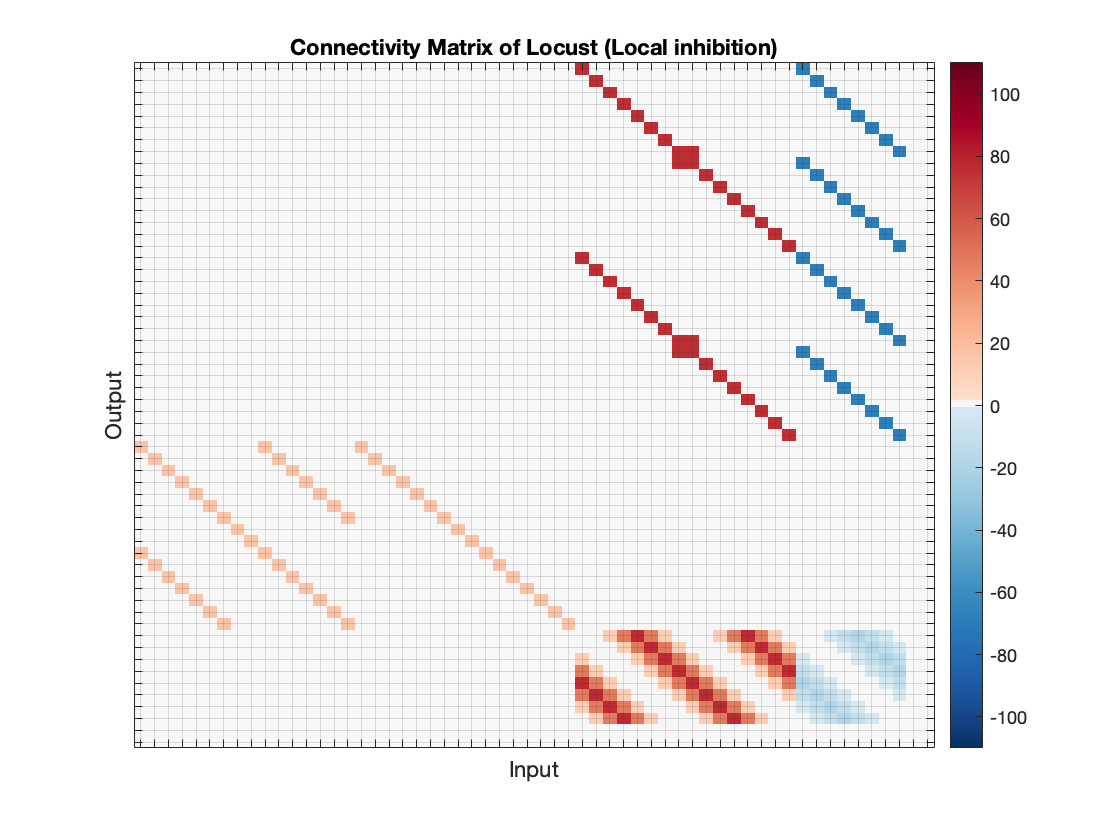

con_matrix(plus_1s_ind)    = plus_1s_value;con_matrix(plus_3s_ind)    = plus_3s_value;con_matrix(plus_1_1s_ind)  = plus_1_1s_value;con_matrix(plus_0_9s_ind)  = plus_0_9s_value;con_matrix(plus_0_5s_ind)  = plus_0_5s_value;con_matrix(plus_0_1s_ind)  = plus_0_1s_value;con_matrix(minus_1s_ind)   = minus_1s_value;con_matrix(minus_1_1s_ind) = minus_1_1s_value;con_matrix(minus_0_9s_ind) = minus_0_9s_value;con_matrix(minus_0_5s_ind) = minus_0_5s_value;con_matrix(minus_0_1s_ind) = minus_0_1s_value;

% Plot the connectivity matrix
plot_con_matrix(con_matrix, 'Connectivity Matrix of Locust (Local inhibition)', 'Input', 'Output', -110, 110, n_P_EN, n_P_EG, n_E_PG, n_Pintr);

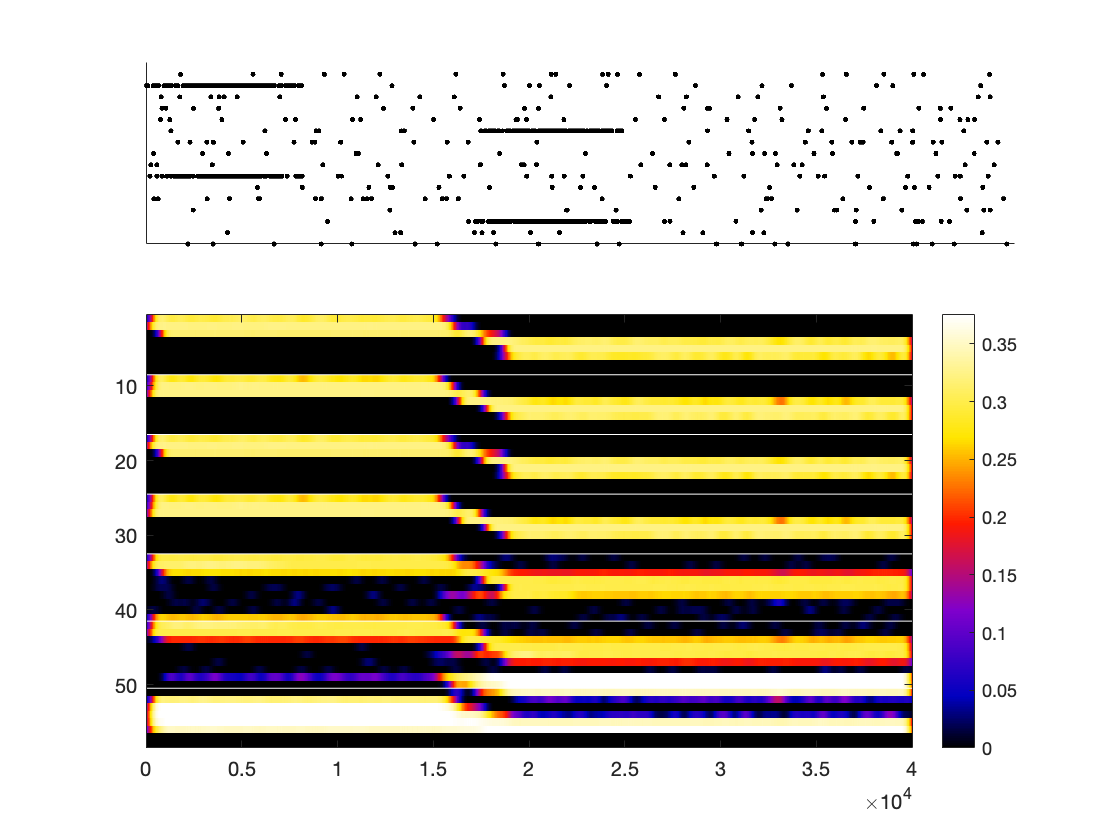

if SAVE_FIG
    title('');
    set(gca, 'FontSize', 16);
    set(findall(gcf, 'type', 'text'), 'FontSize', 16);
    path = './Reports/Report-6/';
    filename = strcat(path, 'connectivity-matrix-locust-local-inhib');
    fig = gcf;
    fig.PaperUnits = 'inches';
    fig.PaperPosition = [0 0 7 6]; % Outer Image size in inches
    print(filename, '-dpng', '-r300');        % Image resolution
    print(filename, '-dpdf', '-r300');        % Image resolution
end

figure();

% Run the network simulation and get bump width at the end
bump = runNetworkSimulation(con_matrix, 1, fixedThreshold, currentStrenth, jumpDistance, pulseLengthMulti, maxSpikeRate, inputList);

if SAVE_FIG
    set(gca, 'FontSize', 16);
    set(findall(gcf, 'type', 'text'), 'FontSize', 16);
    path = './Reports/Report-6/';
    filename = strcat(path, 'locust-sinusoidalinh-jump120deg-extrCurrent0');
    fig = gcf;
    fig.PaperUnits = 'inches';
    fig.PaperPosition = [0 0 7 5.25]; % Outer Image size in inches
end

bumpWidth = bump.bumpWidth;
% Print the bump width
bumpWidth * 180 / pi

ans = 90


bump.bumpLocPre

ans = 2

bump.bumpLocPost

ans = 5


bump.bumpWidthPre  * 180 / pi

ans = 90

bump.bumpWidthPost * 180 / pi

ans = 90


bump.spikeRate % Display the spike rates of the neurons

ans =      0
     0
     0
   210
   230
   220
     0
     0
     0
     0


function plot_con_matrix(con_matrix, title_str, xlabel_str, ylabel_str, z_range_min, z_range_max, n_P_EN, n_P_EG, n_E_PG, n_Pintr)
    plot_con_matrix_V3(con_matrix, title_str, xlabel_str, ylabel_str, z_range_min, z_range_max, n_P_EN, n_P_EG, n_E_PG, n_Pintr, true)
end

function plot_con_matrix_V1(con_matrix, title_str, xlabel_str, ylabel_str, z_range_min, z_range_max)
    figure();
    % Plot the connectivity weight matrix
    surf(con_matrix);
    view(0, 90); % azimuth, elevation
    colorbar;     % show scale colorbar
    %caxis([-20 20]);
    xlabel(xlabel_str);
    ylabel(ylabel_str);
    title(title_str);
    % Set the range of values (colors)
    if ~exist('z_range_min', 'var')
        z_range_min = -100;
    end
    if ~exist('z_range_max', 'var')
        z_range_max = 100;
    end
    caxis([z_range_min z_range_max]);
    
    %% Set the zero value to correspond to black color in the colormap
    cmap = colormap; % Get the colormap values array
    cmap_portion = z_range_max / (z_range_max - z_range_min); % in [0, 1]
    indx = round(cmap_portion * size(cmap, 1)); % Index into the colormap corresponding to data value 0
    cmap(indx, :) = [0.5 0.5 0.5];
    cmap(indx-1, :) = [0.5 0.5 0.5];
    cmap(indx+1, :) = [0.5 0.5 0.5];
    colormap(cmap); % set the new array as the colormap
end

function plot_con_matrix_V2(con_matrix, title_str, xlabel_str, ylabel_str, z_range_min, z_range_max, n_P_EN, n_P_EG, n_E_PG, n_Pintr)
    figure();

    cols_rows_vec = [1:n_P_EN 1:n_P_EG 1:n_E_PG 1:n_Pintr];
    
    ticks = [1:size(con_matrix, 1)];
    
    % Plot the connectivity weight matrix
    imagesc(con_matrix);
    xticks(ticks)
    xticklabels(cols_rows_vec)
    yticks(ticks)
    yticklabels(cols_rows_vec)
    grid on
    colorbar;     % show scale colorbar
    %caxis([-20 20]);
    xlabel(xlabel_str);
    ylabel(ylabel_str);
    title(title_str);
    % Set the range of values (colors)
    if ~exist('z_range_min', 'var')
        z_range_min = -110;
    end
    if ~exist('z_range_max', 'var')
        z_range_max = 110;
    end
    caxis([z_range_min z_range_max]);
    
    %% Set the zero value to correspond to black color in the colormap
    %cmap = colormap; % Get the colormap values array
    %cmap_portion = z_range_max / (z_range_max - z_range_min); % in [0, 1]
    %indx = round(cmap_portion * size(cmap, 1)); % Index into the colormap corresponding to data value 0
    %cmap(indx, :) = [0.5 0.5 0.5];
    %cmap(indx-1, :) = [0.5 0.5 0.5];
    %cmap(indx+1, :) = [0.5 0.5 0.5];
    %colormap(cmap); % set the new array as the colormap
    
    % Blue-Black-Red scale
     m=zeros(101,3);
     b_1to50=linspace(1,0.2,50)';
     r_51to100 = linspace(0.2,1,50)';
     m(1:50,3) = b_1to50;
     m(52:101,1) = r_51to100;
     colormap(m)

    % Blue-White-Red scale
     m=ones(101,3);
     b_1to50=linspace(0.2,1,50)';
     r_51to100 = linspace(1,0.2,50)';
     m(1:50,1) = b_1to50;
     m(1:50,2) = b_1to50;
     m(52:101,2) = r_51to100;
     m(52:101,3) = r_51to100;
     colormap(m)

end


function plot_con_matrix_V3(con_matrix, title_str, xlabel_str, ylabel_str, z_range_min, z_range_max, n_P_EN, n_P_EG, n_E_PG, n_Pintr, no_tick_labels)
    figure();

    cols_rows_vec = [1:n_P_EN 1:n_P_EG 1:n_E_PG 1:n_Pintr];
    
    ticks = [1:size(con_matrix, 1)];
    
    % Plot the connectivity weight matrix
    imagesc(con_matrix);
    xticks(ticks)
    xticklabels(cols_rows_vec)
    yticks(ticks)
    yticklabels(cols_rows_vec)
    if no_tick_labels
        set(gca, 'XTickLabel', []);
        set(gca, 'YTickLabel', []);
    end
    grid on
    colorbar;     % show scale colorbar
    %caxis([-20 20]);
    xlabel(xlabel_str);
    ylabel(ylabel_str);
    title(title_str);
    % Set the range of values (colors)
    if ~exist('z_range_min', 'var')
        z_range_min = -110;
    end
    if ~exist('z_range_max', 'var')
        z_range_max = 110;
    end
    caxis([z_range_min z_range_max]);
    
    %% Set the zero value to correspond to black color in the colormap
    %cmap = colormap; % Get the colormap values array
    %cmap_portion = z_range_max / (z_range_max - z_range_min); % in [0, 1]
    %indx = round(cmap_portion * size(cmap, 1)); % Index into the colormap corresponding to data value 0
    %cmap(indx, :) = [0.5 0.5 0.5];
    %cmap(indx-1, :) = [0.5 0.5 0.5];
    %cmap(indx+1, :) = [0.5 0.5 0.5];
    %colormap(cmap); % set the new array as the colormap
    
    % Blue-Black-Red scale
     m=zeros(101,3);
     b_1to50=linspace(1,0.2,50)';
     r_51to100 = linspace(0.2,1,50)';
     m(1:50,3) = b_1to50;
     m(52:101,1) = r_51to100;
     colormap(m)

    % Blue-White-Red scale
     m=ones(101,3);
     b_1to50=linspace(0.2,1,50)';
     r_51to100 = linspace(1,0.2,50)';
     m(1:50,1) = b_1to50;
     m(1:50,2) = b_1to50;
     m(52:101,2) = r_51to100;
     m(52:101,3) = r_51to100;
     colormap(m)
     
     % Blue-White-Red log scale
     m=ones(201,3);
     b_1to50=logspace(0.1,1,100)'/10;
     r_51to100 = logspace(1,0.1,100)'/10;
     m(1:100,1) = b_1to50;      % R
     m(1:100,2) = b_1to50;      % G
     m(102:201,2) = r_51to100;  % G
     m(102:201,3) = r_51to100;  % B
     colormap(m)
     
     m = brewermap(241, 'RdBu');
     m(100:119, :) = [];
     m(102:121, :) = [];
     m = flipud(m);
     colormap(m);
end


% Copy of function: With added maxSpikeRate input to 
%                   specify the maximum rate of the 
%                   stimulus. Also added return of 
%                   spike rates. 

function bump=runNetworkSimulation(con_matrix, display_plot_bool, fixedThreshold, currentStrenth, jumpDistance, secondPulseLengthMulti, maxSpikeRate, inputList)
    % Run the ring attractor simulation and returns the 
    % width of the maintained bump of activity if any.
    
    simulationTime=4.0;
    stimulusSwitch=[0,0,0,0,0,0,0,0,0,1,0]; % Use the single pulse stimulus
    backgroundNoiseBool = 1;
    
    % Run the ring attractor simulation
    out = PBexperimentModified(con_matrix', display_plot_bool, 1, currentStrenth, jumpDistance, secondPulseLengthMulti, simulationTime, stimulusSwitch, backgroundNoiseBool, inputList, maxSpikeRate);

    % Find the above threshold points and plot them
    %aboveZero=out.V'>-45e-3;;
    %figure();
    %mesh(aboveZero*1);

    % Get the above threshold points with bluring
    blurredImage = out.blurredImage;

    % Get only the first 8 columns which must contain a bump
    firstColumns=blurredImage(:, 1:8);

    % Detect if there was a bump at the end of the simulation
    % Measure activity bump width as width at 50% of maximum
    %lastActivity = firstColumns(end-20,:);
    %lastActivity = firstColumns(end-30:end-20,:); % Get a segment in time
    %lastActivity = mean(lastActivity, 1); % Get the mean of the segment
    %if fixedThreshold
    %    lastActivity=lastActivity>1e-6;
    %else
    %    activityThreshold = (max(lastActivity) - min(lastActivity)) / 2;
    %    lastActivity=lastActivity>activityThreshold;
    %end
    %bumpMargins = diff([0 lastActivity 0]);
    %firstBumpMargins = find(bumpMargins~=0, 2);
    %if size(firstBumpMargins, 2) < 2 % No bump was found
    %    bump.bumpWidth = 0;
    %    bump.bumpLoc   = 0;
    %else
    %    bumpStart = firstBumpMargins(1);
    %    bumpEnd   = firstBumpMargins(2);
    %    % Calculate the bump width in rads
    %    bump.bumpWidth = (((bumpEnd-1) - bumpStart) / 8) * 2 * pi;
    %    bump.bumpLoc   = floor(((bumpEnd-1) + bumpStart) / 2);
    %end
    lastActivity = firstColumns(end-2000:end-1000,:); % Get a segment in time
    lastActivity = mean(lastActivity, 1); % Get the mean of the segment
    bump2 = measureBump1(lastActivity, fixedThreshold);

    lastActivity = firstColumns(end-26000:end-25000,:); % Get a segment in time
    lastActivity = mean(lastActivity, 1); % Get the mean of the segment
    bump1 = measureBump1(lastActivity, fixedThreshold);

    % Set the result
    bump = bump2;
    bump.bumpWidthPre  = bump1.bumpWidth;
    bump.bumpLocPre    = bump1.bumpLoc;
    bump.bumpWidthPost = bump2.bumpWidth;
    bump.bumpLocPost   = bump2.bumpLoc;

    % Return the spike rates of neurons at the end of simulation
    bump.spikeRate = out.spikeRate;
end
